fromPoints = [ -1, 0, 0; 0, 0, 0; 1, 0, 0];
toPoints = [1, 0, 0; 0, 0, 0; -1, 0, 0 ];

fromPointCloud = pointCloud(fromPoints)

fromPointCloud =   pointCloud with properties:

     Location: [3×3 double]
        Color: []
       Normal: []
    Intensity: []
        Count: 3
      XLimits: [-1 1]
      YLimits: [0 0]
      ZLimits: [0 0]


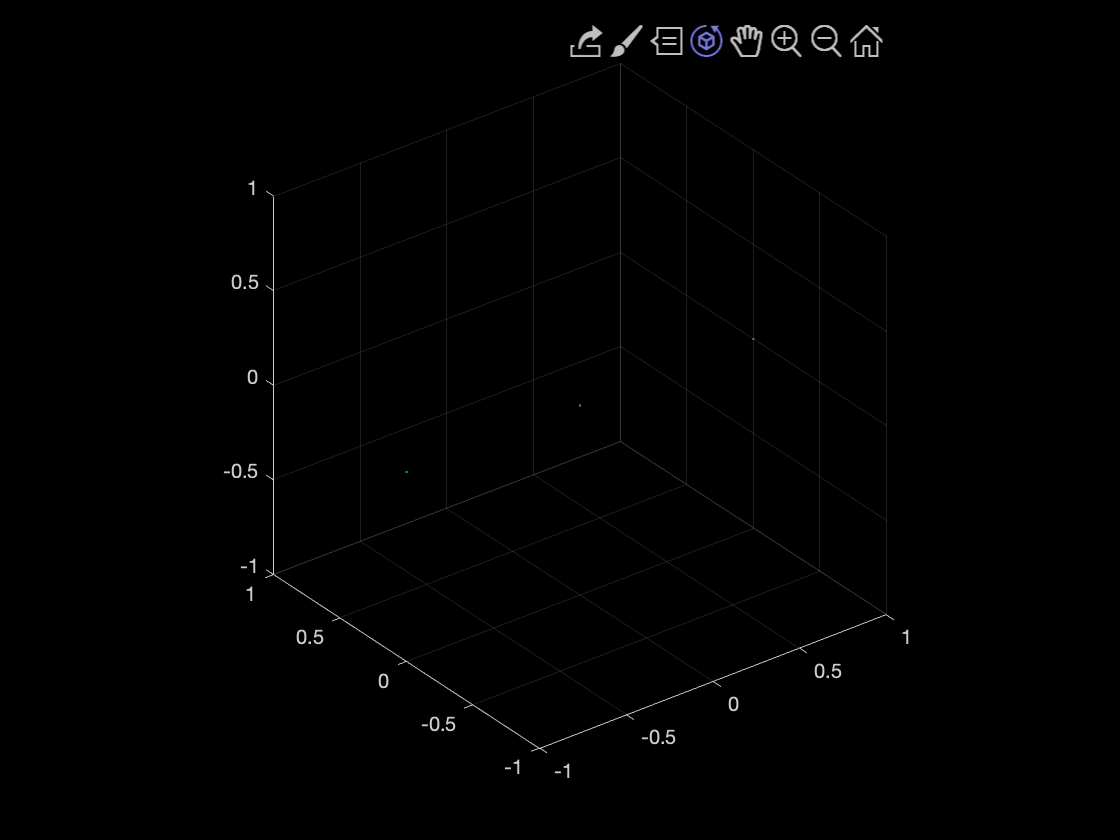

toPointCloud = pointCloud(toPoints);

[tform,movingReg] = pcregistercpd(fromPointCloud,toPointCloud,"Transform","Nonrigid");
pcshowpair(fromPointCloud, toPointCloud)

mat3 = table2array(pointcloudL00F00);

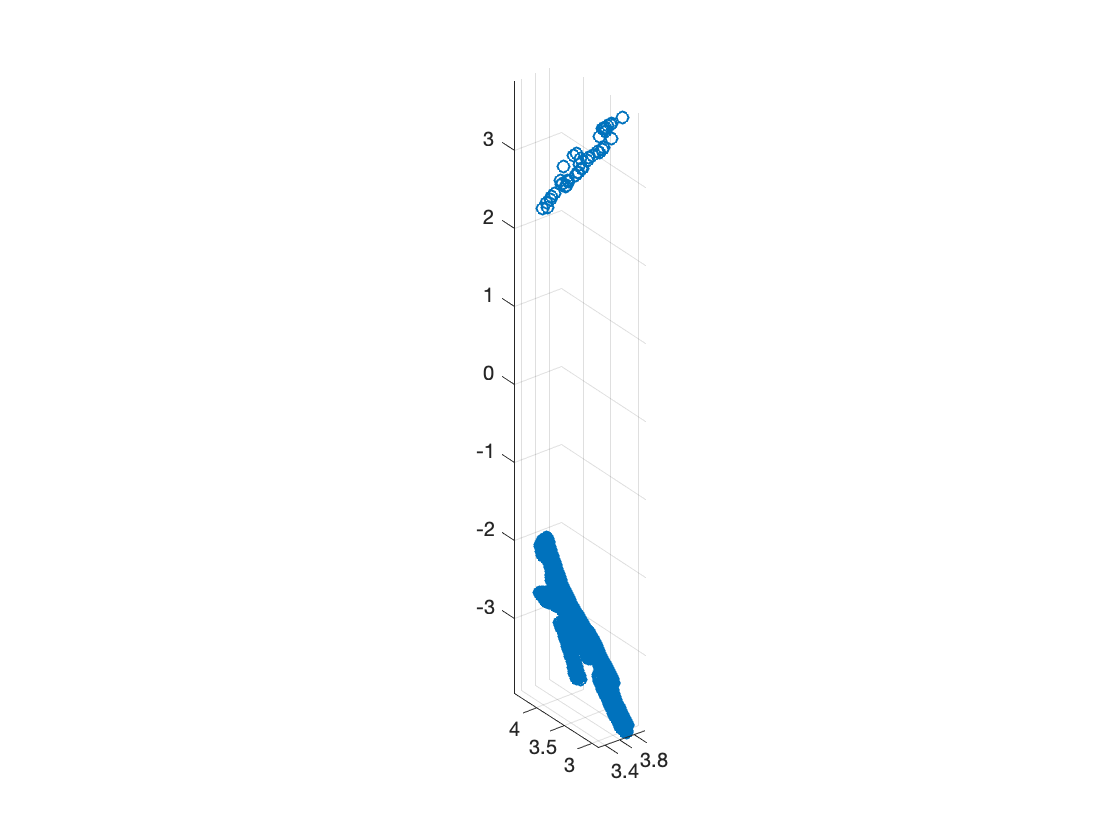


scatter3(mat3(:,1),mat3(:,2),mat3(:,3) )
axis equal